# Decorrélation

Mulcor1 = Multi1;
Mulcor2 = Multi2;
Muldt1 = Multi1;
Muldt2 = Multi2;
for i = 1:length(Multi1)
   for t = 1:length(Multi1{i}) 
        for j = (t):length(Multi1{i})
            [corr, delay] = xcorr(WF.(strcat('1_',string(Multi1{i}(t))))(trig:impul),WF.(strcat('1_',string(Multi1{i}(j))))(trig:impul),'normalized');
            [Mulcor1{i}(t,j), x] = max(corr);
            Muldt1{i}(t,j) = delay(x);
        end
   end
end             
for i = 1:length(Multi2)
   for t = 1:length(Multi2{i}) 
        for j = (t):length(Multi2{i})
            [corr, delay] = xcorr(WF.(strcat('2_',string(Multi2{i}(t))))(trig:impul),WF.(strcat('2_',string(Multi2{i}(j))))(trig:impul),'normalized');
            [Mulcor2{i}(t,j), x] = max(corr);                  
            Muldt2{i}(t,j) = delay(x);
        end
   end
end

## Affichage matrices            

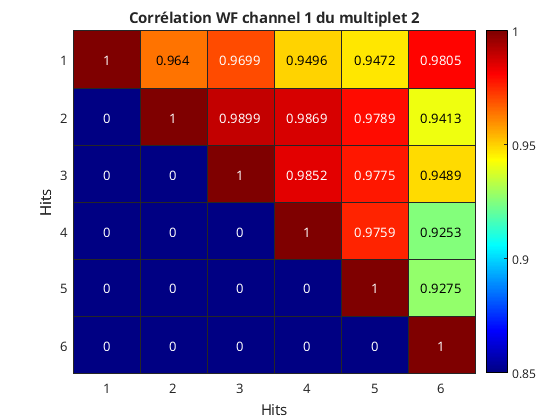

 ;
Num_multi = 2;
figure();
heatmap(Mulcor1{Num_multi});
colormap jet;
title(strcat("Corrélation WF channel 1 du multiplet ",string(Num_multi)));
xlabel('Hits');
ylabel('Hits');
caxis([0.85 1]);

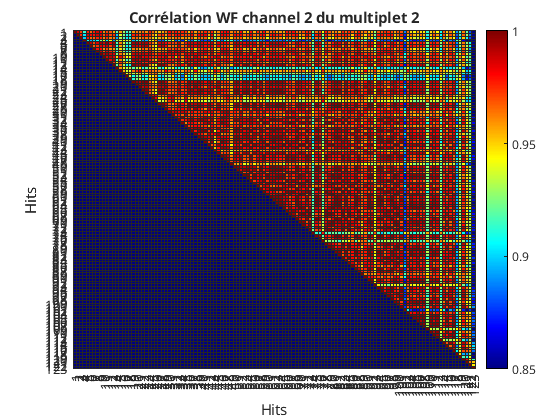

figure();
heatmap(Mulcor2{Num_multi});
colormap jet;
title(strcat("Corrélation WF channel 2 du multiplet ",string(Num_multi)));
xlabel('Hits');
ylabel('Hits');
caxis([0.85 1]);